## Setting up

clear all

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 27-Mar-2023 12:27:56

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 7, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Date", "Price", "Open", "High", "Low", "Vol", "Change"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Vol", "Change"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Vol", "Change"], "ThousandsSeparator", ",");

% Import the data
CrudeOilWTIFuturesHistoricalData = readtable("C:\Politechnika\4 sem\MN\Project_1_MN\Crude Oil WTI Futures Historical Data.csv", opts);

## Clear temporary variables

clear opts

## **Algorithm to calculate MACD value**

Date = CrudeOilWTIFuturesHistoricalData.Date;
Value = CrudeOilWTIFuturesHistoricalData.Price;


EMA26=movmean(Value,26);
EMA12=movmean(Value,12);
MACD_value=EMA12-EMA26;
Signal=movmean(MACD_value,9);

Buy_point= Date(1);
Sell_point=Date(1);
MACD_above = true;

for i = 19:1019 
    if  and(MACD_above==false,MACD_value(i) > Signal(i))
        Sell_point(end+1)=Date(i);
        MACD_above=true;
    end
    if and(MACD_above==true,MACD_value(i) < Signal(i))
        Buy_point(end+1)=Date(i);
        MACD_above=false;
    end
end


## Simulation

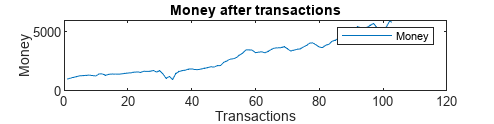

Money = 1000;
Amount_of_oil = 0;
Money_after_sell = Money;
sell_first=false;
Buy_point=flip(Buy_point);
Sell_point=flip(Sell_point);

Control_tab=Date(1);

if Buy_point(1)>Sell_point(1)
    sell_first = true;
end
for i=1:length(Buy_point)-2
    index_buy = find(Date==Buy_point(i));
    index_sell = find(Date==Sell_point(i));
    if(i==32)
        a=25;
    end
    if sell_first
        %sprzedaż nastąpiła szybciej -->  indesk: sell_point + 1 będzie
        %oraz trzeba sprawdzić by nie wyjść poza wartości // ewentualnie
        %skrócić pętle
        index_sell = find(Date==Sell_point(i+1));
        %logika zakupu ropy
        Amount_of_oil=Money/Value(index_buy);
        Money= mod(Money,Value(index_buy));

        %logika sprzedaży ropy
        Money=Money+(Amount_of_oil*Value(index_sell));
        Amount_of_oil=0;
        Money_after_sell(end+1)=Money;
        Control_tab(end+1)=Buy_point(i);
    else
        %kupno nastąpiło wcześniej
        
        %logika zakupu ropy
        Amount_of_oil=Money/Value(index_buy);
        Money= mod(Money,Value(index_buy));

        %logika sprzedaży ropy
        Money=Money+(Amount_of_oil*Value(index_sell));
        Amount_of_oil=0;
        Money_after_sell(end+1)=Money;
    end
end

plot(Money_after_sell);
xlabel('Transactions');
ylabel('Money');
legend('Money');
title('Money after transactions');
set(gcf, "Position",[0,0,1200,300]);
print('money', '-dpng');

## Plotting

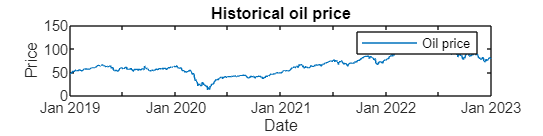

xl = [datetime('02/01/2019', 'InputFormat','MM/dd/uuuu'), datetime('04/01/2019', 'InputFormat','MM/dd/uuuu')];
xl2 = [datetime('05/01/2020', 'InputFormat','MM/dd/uuuu'), datetime('07/01/2020', 'InputFormat','MM/dd/uuuu')];
xl3 = [datetime('02/20/2020', 'InputFormat','MM/dd/uuuu'), datetime('04/20/2020', 'InputFormat','MM/dd/uuuu')];

plot(Date, Value);
legend({'Price'});
legend({'Oil price'});
xlabel('Date');
ylabel('Price');
title('Historical oil price');
%set(gcf, "Position",[0,0,1200,300]);
print('Oil_price_full', '-dpng');

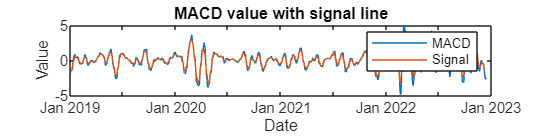


plot(Date, MACD_value);
hold on
plot(Date, Signal);
legend({'MACD','Signal'});
xlabel('Date');
ylabel('Value');
title('MACD value with signal line');
hold off
print('MACD_value_full', '-dpng');

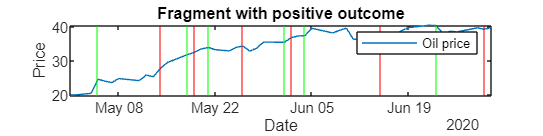



plot(Date, Value);
xline(Sell_point, 'r', 'DisplayName', 'Sell point');
xline(Buy_point, 'g', 'DisplayName', 'Buy point');
legend({'Price'});
legend({'Oil price'});
xlabel('Date');
ylabel('Price');
title('Fragment with positive outcome');
xlim(xl2);
print('Oil_price_frag_przychod', '-dpng');

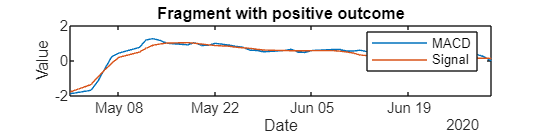


plot(Date, MACD_value);
hold on
plot(Date, Signal);
legend({'MACD','Signal'});
xlabel('Date');
ylabel('Value');
title('Fragment with positive outcome');
xlim(xl2);
hold off
print('MACD_value_frag_przychod', '-dpng');

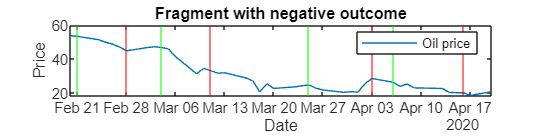


plot(Date, Value);
xline(Sell_point, 'r', 'DisplayName', 'Sell point');
xline(Buy_point, 'g', 'DisplayName', 'Buy point');
legend({'Price'});
legend({'Oil price'});
xlabel('Date');
ylabel('Price');
title('Fragment with negative outcome');
xlim(xl3);
print('Oil_price_frag_strata', '-dpng');

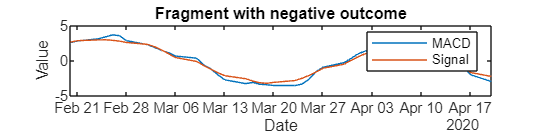


plot(Date, MACD_value);
hold on
plot(Date, Signal);
legend({'MACD','Signal'});
xlabel('Date');
ylabel('Value');
title('Fragment with negative outcome');
xlim(xl3);
hold off
print('MACD_value_frag_strata', '-dpng');

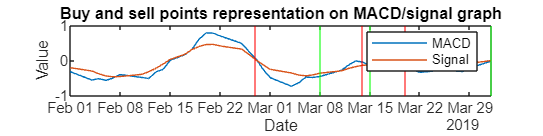




plot(Date, MACD_value);
hold on
plot(Date, Signal);
xline(Sell_point, 'r', 'DisplayName', 'Sell point');
xline(Buy_point, 'g', 'DisplayName', 'Buy point');
legend({'MACD','Signal'});
xlabel('Date');
ylabel('Value');
title('Buy and sell points representation on MACD/signal graph');
xlim(xl);
print('Buy_sell_with_MACD', '-dpng');

hold off

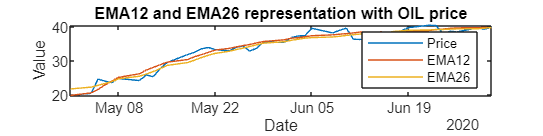

plot(Date, Value);
hold on
plot(Date, EMA12);
plot(Date, EMA26);
legend({'Price','EMA12', 'EMA26'});
xlabel('Date');
ylabel('Value');
title('EMA12 and EMA26 representation with OIL price');
xlim(xl2);
hold off
print('EMA12_and_EMA26_with_OIL', '-dpng');

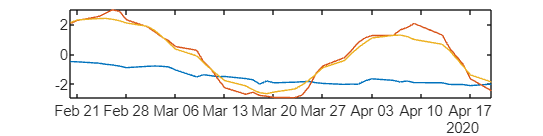




V=normalize(Value);
[M,C,S]=normalize(MACD_value);
Sig=normalize(Signal,"center",C,"scale",S);
plot(Date, V, Date, M,Date, Sig);
%line(Sell_point, 'r');
%xline(Buy_point, 'g');
xlim(xl3);